POSITION_VEC = [3,3,3.3,2.7];

set(0, 'DefaultLineLineWidth', 1);
colororder({'#0072BD','#D95319','#EDB120','#7E2F8E','#80F2E0','#FFD399','#F0F0A0','#FEAFFF'});

## Riley's Data

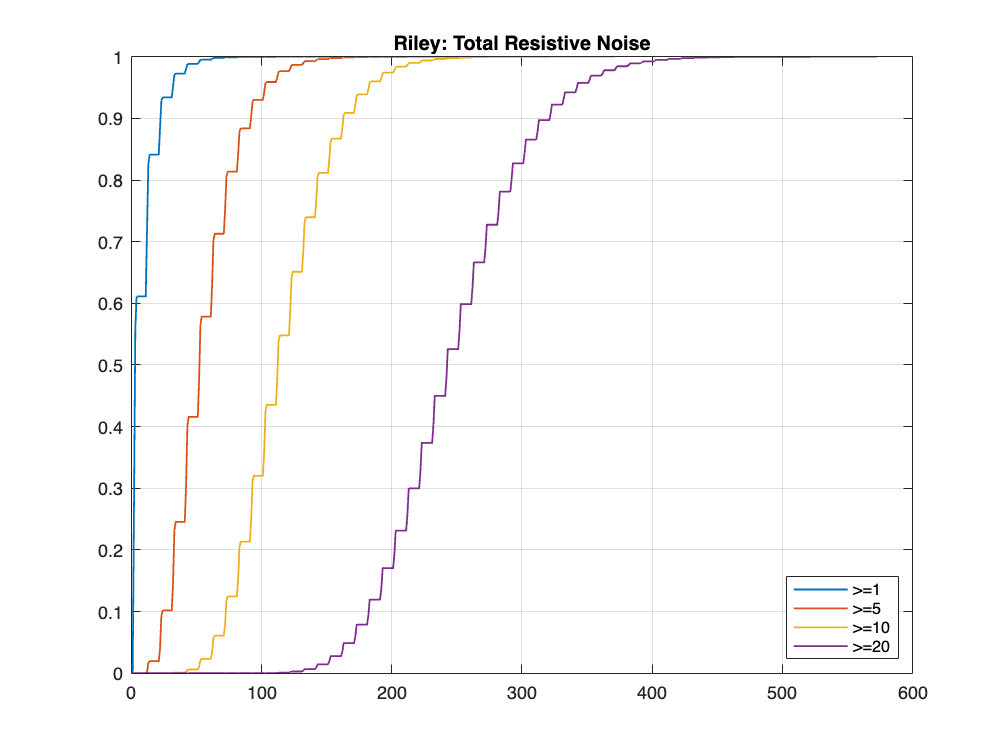

data = readmatrix('Data/Riley/Resistive1.csv');
resist_riley_1_x=data(1:2:end);
resist_riley_1_y=data(2:2:end);

data = readmatrix('Data/Riley/Resistive5.csv');
resist_riley_5_x=data(1:2:end);
resist_riley_5_y=data(2:2:end);

data = readmatrix('Data/Riley/Resistive10.csv');
resist_riley_10_x=data(1:2:end);
resist_riley_10_y=data(2:2:end);

data = readmatrix('Data/Riley/Resistive20.csv');
resist_riley_20_x=data(1:2:end);
resist_riley_20_y=data(2:2:end);

plot(resist_riley_1_x,resist_riley_1_y, ...
     resist_riley_5_x,resist_riley_5_y, ...
     resist_riley_10_x,resist_riley_10_y, ...
     resist_riley_20_x,resist_riley_20_y);
grid on;
title("Riley: Total Resistive Noise");
legend(">=1",">=5",">=10",">=20","Location","southeast");

## Ben's Data

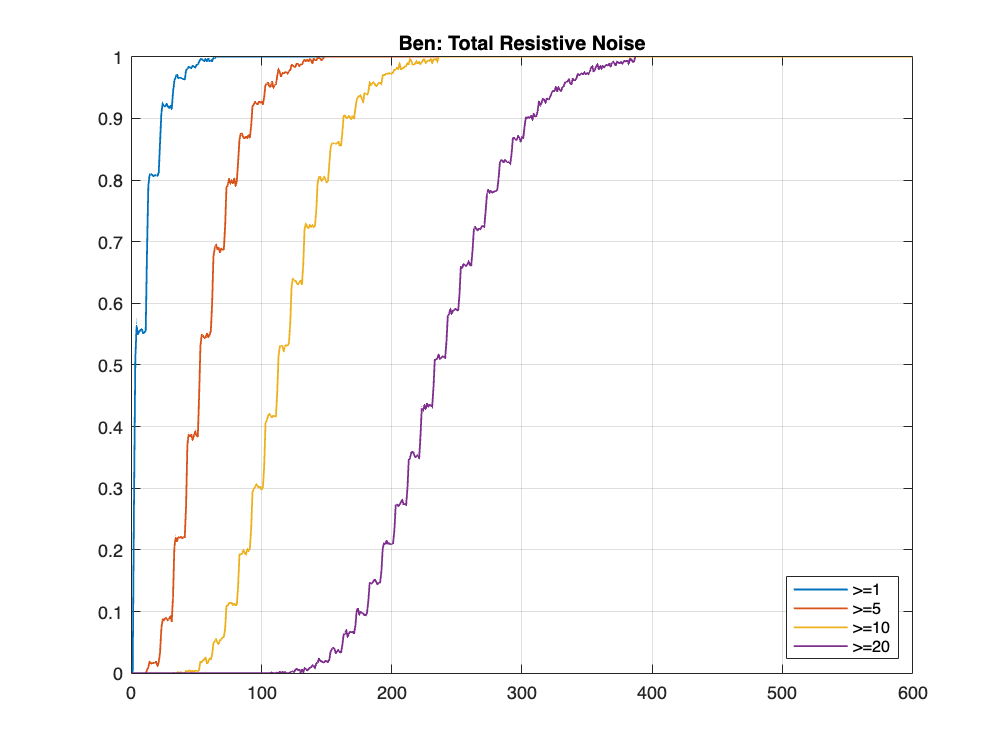

data = readmatrix('Data/Ben/Resistive1.csv');
resist_ben_1_x=data(1:2:end);
resist_ben_1_y=data(2:2:end);

data = readmatrix('Data/Ben/Resistive5.csv');
resist_ben_5_x=data(1:2:end);
resist_ben_5_y=data(2:2:end);

data = readmatrix('Data/Ben/Resistive10.csv');
resist_ben_10_x=data(1:2:end);
resist_ben_10_y=data(2:2:end);

data = readmatrix('Data/Ben/Resistive20.csv');
resist_ben_20_x=data(1:2:end);
resist_ben_20_y=data(2:2:end);

plot(resist_ben_1_x,resist_ben_1_y, ...
     resist_ben_5_x,resist_ben_5_y, ...
     resist_ben_10_x,resist_ben_10_y, ...
     resist_ben_20_x,resist_ben_20_y);
grid on;
title("Ben: Total Resistive Noise");
legend(">=1",">=5",">=10",">=20","Location","southeast");

## Jonah's Data

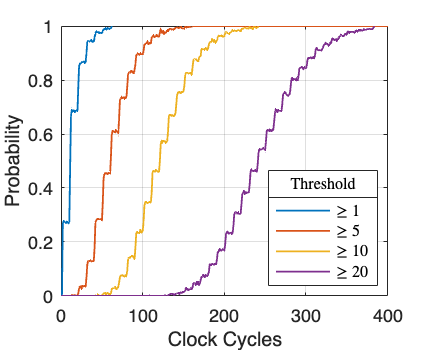

data = readmatrix('Data/Jonah/Resistive/post_2x2_1.csv');
resist_jonah_1_x=data(1:2:end);
resist_jonah_1_y=data(2:2:end);

data = readmatrix('Data/Jonah/Resistive/post_2x2_5.csv');
resist_jonah_5_x=data(1:2:end);
resist_jonah_5_y=data(2:2:end);

data = readmatrix('Data/Jonah/Resistive/post_2x2_10.csv');
resist_jonah_10_x=data(1:2:end);
resist_jonah_10_y=data(2:2:end);

data = readmatrix('Data/Jonah/Resistive/post_2x2_20.csv');
resist_jonah_20_x=data(1:2:end);
resist_jonah_20_y=data(2:2:end);

fig = figure("Units","inches","Position",POSITION_VEC);

plot(resist_jonah_1_x,resist_jonah_1_y, ...
     resist_jonah_5_x,resist_jonah_5_y, ...
     resist_jonah_10_x,resist_jonah_10_y, ...
     resist_jonah_20_x,resist_jonah_20_y);
grid on;
xlabel("Clock Cycles");
ylabel("Probability");
xlim([0,400]);
leg = legend(["$\ge 1$","$\ge 5$","$\ge 10$","$\ge 20$"],"Location","southeast","Interpreter","Latex");
title(leg, "Threshold", "Interpreter","latex");
exportgraphics(fig, "VMCAI_25/2x2_resistive_final.png", "Resolution",300);

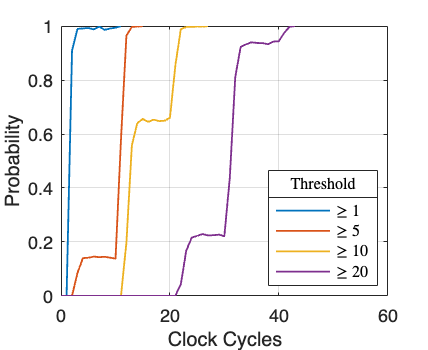

data = readmatrix('Data/Jonah/Resistive/uniform_3x3_1.csv');
resist_jonah_1_x=data(1:2:end);
resist_jonah_1_y=data(2:2:end);

data = readmatrix('Data/Jonah/Resistive/uniform_3x3_5.csv');
resist_jonah_5_x=data(1:2:end);
resist_jonah_5_y=data(2:2:end);

data = readmatrix('Data/Jonah/Resistive/uniform_3x3_10.csv');
resist_jonah_10_x=data(1:2:end);
resist_jonah_10_y=data(2:2:end);

data = readmatrix('Data/Jonah/Resistive/uniform_3x3_20.csv');
resist_jonah_20_x=data(1:2:end);
resist_jonah_20_y=data(2:2:end);

fig = figure("Units","inches","Position",POSITION_VEC);

plot(resist_jonah_1_x,resist_jonah_1_y, ...
     resist_jonah_5_x,resist_jonah_5_y, ...
     resist_jonah_10_x,resist_jonah_10_y, ...
     resist_jonah_20_x,resist_jonah_20_y);
grid on;
xlabel("Clock Cycles");
ylabel("Probability");
xlim([0,60]);
leg = legend(["$\ge 1$","$\ge 5$","$\ge 10$","$\ge 20$"],"Location","southeast","Interpreter","Latex");
title(leg, "Threshold", "Interpreter","latex");
exportgraphics(fig, "VMCAI_25/3x3_resistive_final.png", "Resolution",300);

## Comparing Jonah, Ben and Riley's Resistive Noise

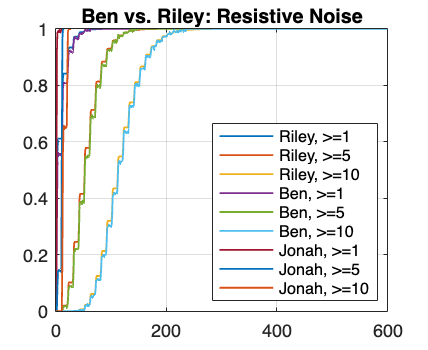

plot(resist_riley_1_x,resist_riley_1_y, ...
     resist_riley_5_x,resist_riley_5_y, ...
     resist_riley_10_x,resist_riley_10_y, ...
     resist_ben_1_x,resist_ben_1_y, ...
     resist_ben_5_x,resist_ben_5_y, ...
     resist_ben_10_x,resist_ben_10_y, ...
     resist_jonah_1_x,resist_jonah_1_y, ...
     resist_jonah_5_x,resist_jonah_5_y, ...
     resist_jonah_10_x,resist_jonah_10_y);
grid on;
title("Ben vs. Riley: Resistive Noise");
legend("Riley, >=1","Riley, >=5","Riley, >=10", ...
       "Ben, >=1","Ben, >=5","Ben, >=10", ...
       "Jonah, >=1","Jonah, >=5","Jonah, >=10", ...
       "Location","southeast");

## Comparing Jonah and Ben's Resistive Noise

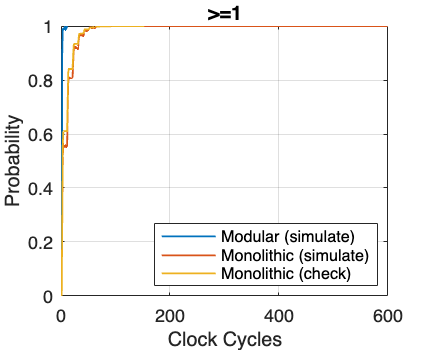

plot(resist_jonah_1_x,resist_jonah_1_y, ...
    resist_ben_1_x,resist_ben_1_y, ...
    resist_riley_1_x,resist_riley_1_y);
grid on;
xlabel("Clock Cycles");
ylabel("Probability");
title(">=1");
legend("Modular (simulate)","Monolithic (simulate)","Monolithic (check)","Location","southeast");

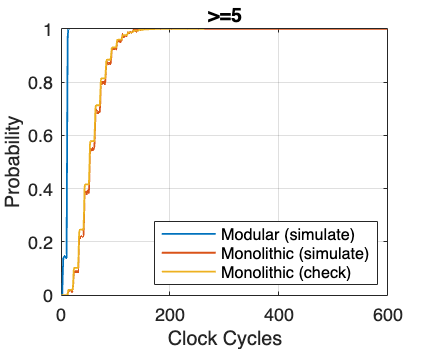


plot(resist_jonah_5_x,resist_jonah_5_y, ...
    resist_ben_5_x,resist_ben_5_y, ...
    resist_riley_5_x,resist_riley_5_y);
grid on;
xlabel("Clock Cycles");
ylabel("Probability");
title(">=5");
legend("Modular (simulate)","Monolithic (simulate)","Monolithic (check)","Location","southeast");

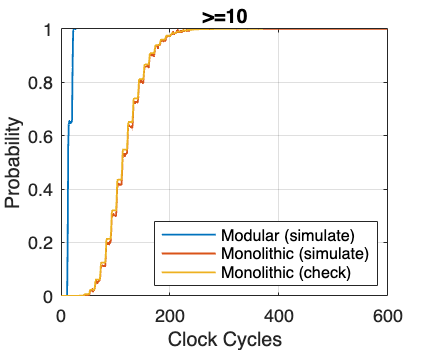


plot(resist_jonah_10_x,resist_jonah_10_y, ...
    resist_ben_10_x,resist_ben_10_y, ...
    resist_riley_10_x,resist_riley_10_y);
grid on;
xlabel("Clock Cycles");
ylabel("Probability");
title(">=10");
legend("Modular (simulate)","Monolithic (simulate)","Monolithic (check)","Location","southeast");

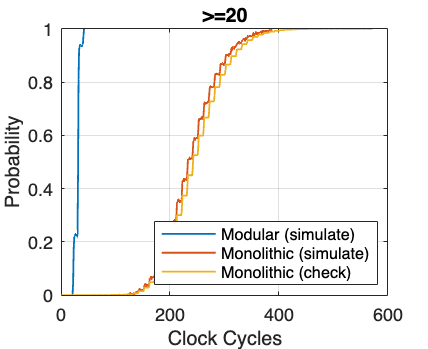


plot(resist_jonah_20_x,resist_jonah_20_y, ...
    resist_ben_20_x,resist_ben_20_y, ...
    resist_riley_20_x,resist_riley_20_y);
grid on;
xlabel("Clock Cycles");
ylabel("Probability");
title(">=20");
legend("Modular (simulate)","Monolithic (simulate)","Monolithic (check)","Location","southeast");

## Forming a model closer to that of Robert's

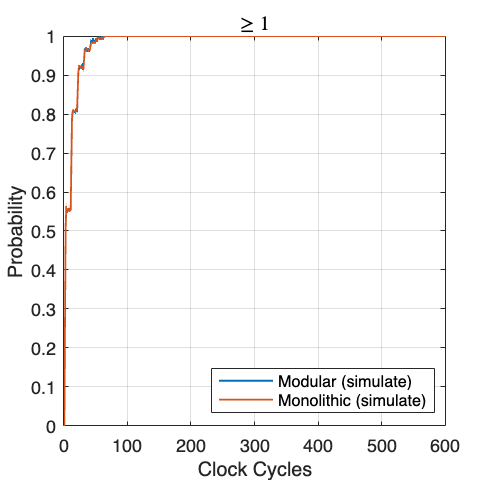

data = readmatrix('Data/Jonah/Journal/s1-r1.csv');
resist_jonah_1_x=data(1:2:end);
resist_jonah_1_y=data(2:2:end);

data = readmatrix('Data/Jonah/Journal/s1-r5.csv');
resist_jonah_5_x=data(1:2:end);
resist_jonah_5_y=data(2:2:end);

data = readmatrix('Data/Jonah/Journal/s1-r10.csv');
resist_jonah_10_x=data(1:2:end);
resist_jonah_10_y=data(2:2:end);

data = readmatrix('Data/Jonah/Journal/s1-r20.csv');
resist_jonah_20_x=data(1:2:end);
resist_jonah_20_y=data(2:2:end);

fig = figure("Units","inches","Position",[3,3,3.8,3.7]);

plot(resist_jonah_1_x,resist_jonah_1_y, ...
    resist_ben_1_x,resist_ben_1_y);
grid on;
xlabel("Clock Cycles");
ylabel("Probability");
title("$\ge 1$", 'Interpreter','latex');
legend("Modular (simulate)","Monolithic (simulate)","Location","southeast");

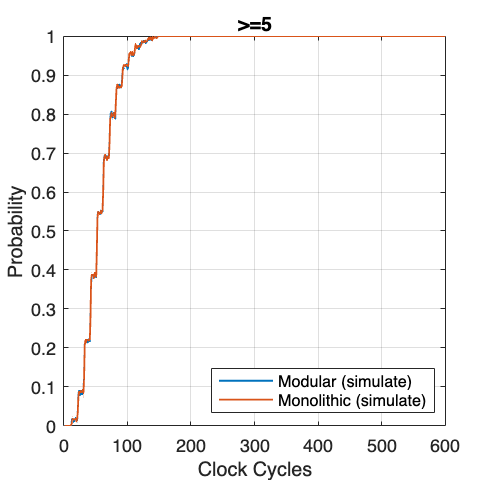



plot(resist_jonah_5_x,resist_jonah_5_y, ...
    resist_ben_5_x,resist_ben_5_y);
grid on;
xlabel("Clock Cycles");
ylabel("Probability");
title(">=5");
legend("Modular (simulate)","Monolithic (simulate)","Location","southeast");

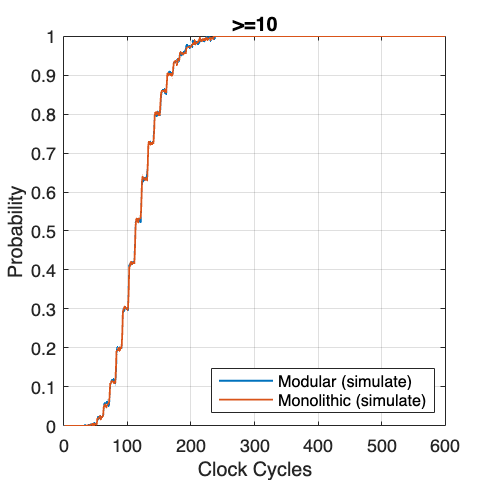


plot(resist_jonah_10_x,resist_jonah_10_y, ...
    resist_ben_10_x,resist_ben_10_y);
grid on;
xlabel("Clock Cycles");
ylabel("Probability");
title(">=10");
legend("Modular (simulate)","Monolithic (simulate)","Location","southeast");

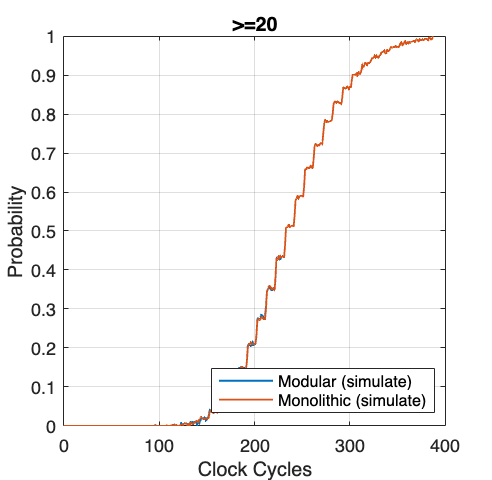


plot(resist_jonah_20_x,resist_jonah_20_y, ...
    resist_ben_20_x,resist_ben_20_y);
grid on;
xlabel("Clock Cycles");
ylabel("Probability");
title(">=20");
legend("Modular (simulate)","Monolithic (simulate)","Location","southeast");

## Good Resistive

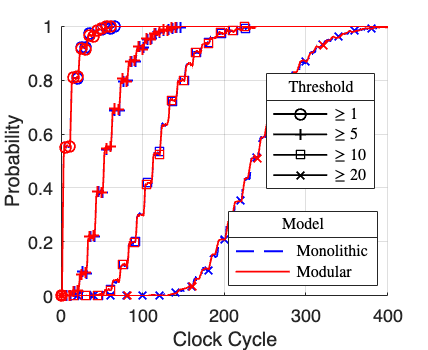

new_data = readtable("Data/Nick/noise_2x2_20.txt");
resist_jonah_20_x = new_data{:,"CLK_UPPER"};
resist_jonah_20_y = new_data{:,"resistiveNoiseProbability"};

fig_r = figure(Units="inches", Position=POSITION_VEC);
hold on;

p(1) = plot(nan,nan,'b--');
plot(resist_ben_1_x,resist_ben_1_y, 'b--');
p1(1) = plot(resist_ben_1_x,resist_ben_1_y, 'b--', 'Marker','o', 'MarkerIndices',1:5:length(resist_ben_5_y));
p1(2) = plot(resist_ben_5_x,resist_ben_5_y, 'b--', 'Marker','+', 'MarkerIndices',1:5:length(resist_ben_5_y));
p1(3) = plot(resist_ben_10_x,resist_ben_10_y, 'b--', 'Marker','square', 'MarkerIndices',1:15:length(resist_ben_10_y));
p1(4) = plot(resist_ben_20_x,resist_ben_20_y, 'b--', 'Marker','x', 'MarkerIndices',1:20:length(resist_ben_20_y));

p(2) = plot(nan,nan,'r');
plot(resist_jonah_1_x,resist_jonah_1_y, 'r', 'Marker','o', 'MarkerIndices',1:5:length(resist_jonah_5_y));
plot(resist_jonah_5_x,resist_jonah_5_y, 'r', 'Marker','+', 'MarkerIndices',1:5:length(resist_jonah_5_y));
plot(resist_jonah_10_x,resist_jonah_10_y, 'r', 'Marker','square', 'MarkerIndices',1:15:length(resist_jonah_10_y));
plot(resist_jonah_20_x,resist_jonah_20_y, 'r', 'Marker','x', 'MarkerIndices',1:20:length(resist_jonah_20_y));

leg1 = legend(p, ["Monolithic", "Modular"], "Location","southeast",'Interpreter','latex');
title(leg1, "Model");

grid on
xlabel("Clock Cycle");
ylabel("Probability");
xlim([0, 400]);

ax2 = axes('position',get(gca,'position'),'visible','off');
hold on
p2(1) = plot(nan,nan,'Marker','o','Color','black');
p2(2) = plot(nan,nan,'Marker','+','Color','black');
p2(3) = plot(nan,nan,'Marker','square','Color','black');
p2(4) = plot(nan,nan,'Marker','x','Color','black');
hold off

leg2 = legend(ax2, p2, ["$\ge 1$", "$\ge 5$", "$\ge 10$", "$\ge 20$"], 'Location','none','Position',[0.6227 0.4607 0.2540, 0.3271], "Interpreter","latex");
title(leg2,  "Threshold");

exportgraphics(fig_r, "VMCAI_25/final_resist_comparison.png", "Resolution",600);

## Bad resistive

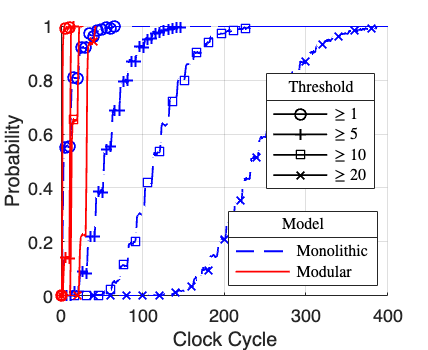

data = readmatrix('Data/Jonah/Resistive/uniform_3x3_1.csv');
resist_jonah_1_x=data(1:2:end);
resist_jonah_1_y=data(2:2:end);

data = readmatrix('Data/Jonah/Resistive/uniform_3x3_5.csv');
resist_jonah_5_x=data(1:2:end);
resist_jonah_5_y=data(2:2:end);

data = readmatrix('Data/Jonah/Resistive/uniform_3x3_10.csv');
resist_jonah_10_x=data(1:2:end);
resist_jonah_10_y=data(2:2:end);

data = readmatrix('Data/Jonah/Resistive/uniform_3x3_20.csv');
resist_jonah_20_x=data(1:2:end);
resist_jonah_20_y=data(2:2:end);

fig_r = figure(Units="inches", Position=POSITION_VEC);
hold on;

p(1) = plot(nan,nan,'b--');
plot(resist_ben_1_x,resist_ben_1_y, 'b--');
p1(1) = plot(resist_ben_1_x,resist_ben_1_y, 'b--', 'Marker','o', 'MarkerIndices',1:5:length(resist_ben_5_y));
p1(2) = plot(resist_ben_5_x,resist_ben_5_y, 'b--', 'Marker','+', 'MarkerIndices',1:5:length(resist_ben_5_y));
p1(3) = plot(resist_ben_10_x,resist_ben_10_y, 'b--', 'Marker','square', 'MarkerIndices',1:15:length(resist_ben_10_y));
p1(4) = plot(resist_ben_20_x,resist_ben_20_y, 'b--', 'Marker','x', 'MarkerIndices',1:20:length(resist_ben_20_y));

p(2) = plot(nan,nan,'r');
plot(resist_jonah_1_x,resist_jonah_1_y, 'r', 'Marker','o', 'MarkerIndices',1:5:length(resist_jonah_5_y));
plot(resist_jonah_5_x,resist_jonah_5_y, 'r', 'Marker','+', 'MarkerIndices',1:5:length(resist_jonah_5_y));
plot(resist_jonah_10_x,resist_jonah_10_y, 'r', 'Marker','square', 'MarkerIndices',1:15:length(resist_jonah_10_y));
plot(resist_jonah_20_x,resist_jonah_20_y, 'r', 'Marker','x', 'MarkerIndices',1:20:length(resist_jonah_20_y));

leg1 = legend(p, ["Monolithic", "Modular"], "Location","southeast",'Interpreter','latex');
title(leg1, "Model");

grid on
xlabel("Clock Cycle");
ylabel("Probability");
xlim([0, 400]);

ax2 = axes('position',get(gca,'position'),'visible','off');
hold on
p2(1) = plot(nan,nan,'Marker','o','Color','black');
p2(2) = plot(nan,nan,'Marker','+','Color','black');
p2(3) = plot(nan,nan,'Marker','square','Color','black');
p2(4) = plot(nan,nan,'Marker','x','Color','black');
hold off

leg2 = legend(ax2, p2, ["$\ge 1$", "$\ge 5$", "$\ge 10$", "$\ge 20$"], 'Location','none','Position',[0.6227 0.4607 0.2540, 0.3271], "Interpreter","latex");
title(leg2,  "Threshold");

exportgraphics(fig_r, "VMCAI_25/incorrect_resist_comparison.png", "Resolution",600);